clear;clc;
close all;

folderPath = fullfile(pwd, '250424-M-Kernel-bloch');
if ~exist(folderPath, 'dir')
mkdir(folderPath);
end

jlmrsData.measure.pulse_type = 'FID'

jlmrsData = 包含以下字段的 struct :
    measure: [1×1 struct]


data.basic.gamma = 2.6752e+08;  % [rad/s/T] Gyromagnetic Ratio 
data.basic.B0 = 48000e-9; 
data.basic.Delta = 0;  % [rad/s] Resonance frequency offset
data.basic.theta = 0;  % [°] The phase of excitation field
data.basic.T1relax = 1000;  % [ms] Longitudinal relaxation time T1
% data.basic.T2relax = 100;  % [ms] Transversal relaxation time T2
% T1relax = [10, 100, 200, 500, 800, 1000];
T2relax = [1000];

data.basic.trep = 100;  
% Meaning of 'trep' depends on the pulse sequence type:
% - FID  : Total duration of the sequence (including excitation and signal acquisition)
% - SE   : Sum of the 90° excitation pulse duration and relaxation (echo) time
% - SSFP : Periodic repetition interval between successive RF excitations

tp_ratio_data = logspace(log10(0.01), log10(0.9), 6);  % Single cycle excitation duty cycle
% tp_ratio_data = 0.20;

B1 = logspace(-12, -5, 20000);  % [T] The amplitude of the alternating field in the x–y plane
m_ssfp = [];

tic;
for tprn = 1:length(tp_ratio_data)
    tp_ratio = tp_ratio_data(tprn);  % Single cycle excitation duty cycle
    data.basic.tp = data.basic.trep*tp_ratio;  % [ms] Single cycle excitation time
    
    for T2n = 1:length(T2relax)
        data.basic.T2relax = T2relax(T2n);
        % Parameters of the Bloch equation for a steady-state precession sequence
        odeparam = [];  
        odeparam.gamma = data.basic.gamma; 
        odeparam.B1 = B1;
        odeparam.Delta = data.basic.Delta; 
        odeparam.theta = data.basic.theta;
        odeparam.T1 = data.basic.T1relax/1e3;
        odeparam.T2 = data.basic.T2relax/1e3;
        odeparam.pulseparam.trep = data.basic.trep/1e3;
        odeparam.pulseparam.tp = data.basic.tp/1e3;
    
        % SD-MEI algorithm to solve the magnetization vector
        switch jlmrsData.measure.pulse_type
            case 'FID'
                M_data = SDMEI_BLOCH_FID(odeparam);  
            case 'SSFP'
                M_data = SDMEI_BLOCH_SSFP(odeparam);
        end
        % Extract the magnetization vector of the Mxy component of interest
        m_ssfp =[m_ssfp; M_data(3,:)]; 
    end
end
elapsedTime = toc;
fprintf('Time: %.2f 秒\n', elapsedTime);

Time: 1.98 秒


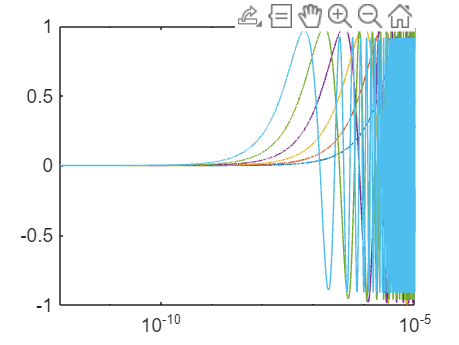

% Draw the magnetization vector diagram under different B1 conditions
semilogx(B1,m_ssfp(1,:))
hold on; semilogx(B1,m_ssfp(2,:))
hold on; semilogx(B1,m_ssfp(3,:))
hold on; semilogx(B1,m_ssfp(4,:))
hold on; semilogx(B1,m_ssfp(5,:))
hold on; semilogx(B1,m_ssfp(6,:))

% save(fullfile(pwd, ['100-1000-100-bloch-250507','.mat']), ...
%     "B1",'m_ssfp');